# Modelagem dinâmica a partir da dados reais

## Boas Praticas

close all;
clear all;
clc;

## Lendo os dados reais a partir de um modelo .txt

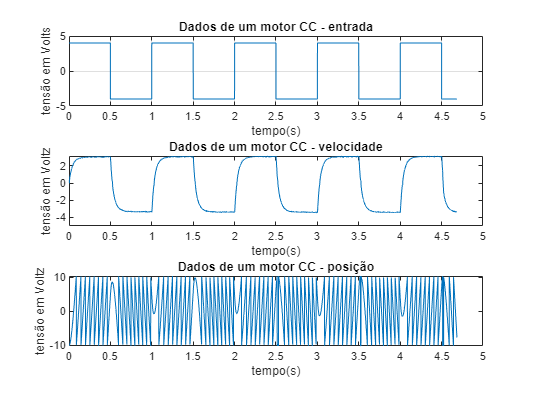

leitordados;

T = 1e-3;
N = length(ent);

tempo = linspace(0,N*T,N);

figure(1)
subplot(3,1,1)
plot(tempo,ent)
title('Dados de um motor CC - entrada')
xlabel('tempo(s)')
ylabel('tensão em Volts')
grid

subplot(3,1,3)
plot(tempo,xyz)
title('Dados de um motor CC - posição')
xlabel('tempo(s)')
ylabel('tensão em Voltz')

subplot(3,1,2)
plot(tempo,vel)
title('Dados de um motor CC - velocidade')
xlabel('tempo(s)')
ylabel('tensão em Voltz')

## Estimando um modelo em Laplace para os dados

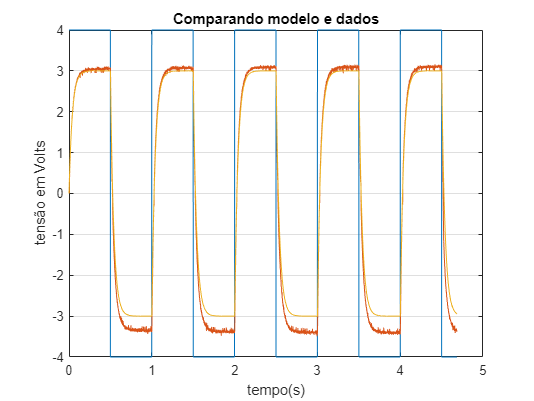

km = 18.9;
pm = 25.19;

ft = tf(km,[1 pm]);

ym = lsim(ft, ent, tempo);

figure(2)
plot(tempo,ent,tempo,vel,tempo,ym)
title('Comparando modelo e dados')
xlabel('tempo(s)')
ylabel('tensão em Volts')
grid

## Sintonizando os valores do modelo a partir dos dados

x0 = [1 1];
x = fminsearch(@(x) ErroQuadratico, vel, )

Unrecognized function or variable 'ErroQuadratico'.

Error in Modelagem (line 44)
x = fminsearch(@(x) ErroQuadratico, vel)

Error in fminsearch (line 201)
fv(:,1) = funfcn(x,varargin{:});

## Comparando o modelo com os dados